# Image Thresholding Practice 

## Problem 1

How can you enhance the provided code to accurately draw circles around all blue pucks in the image (images used for this problem are Puck_1.png, Puck_2.png, and Puck_3.png)?

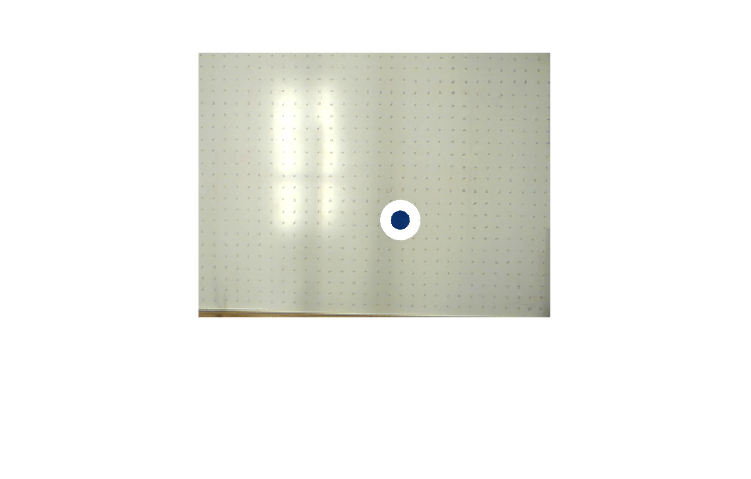

% Clear the command window and workspace to start fresh
clc;
clear;

% Ask the user for the filename of the image they want to process
filename = input('Enter the filename: ', 's');

% Read the image file


% Get the dimensions of the image: height, width, and color channels


% Initialize a binary mask to identify certain colors in the image
binary = false(height, width);

% Initialize variables for calculating centroid and area
row = 0;
col = 0;
count = 0;

% Iterate through each pixel in the image
for ii = 1:height
    for jj = 1:width
        
        % Extract the red, green, and blue color components of the pixel
        
        
        % Check if the pixel's color falls within a certain range
        if red > 0 && red < 65 && green > 30 && green < 100 && blue > 90 && blue < 170
            
            % If the color matches, set the corresponding pixel in the binary mask to true
            binary(ii, jj) = 1;
            
            % Update variables for calculating centroid and area
            row = row + ii;
            col = col + jj;
            count = count + 1;
        end
    end
end

% Calculate centroid coordinates and radius based on the identified pixels
row = row / count;
col = col / count;
radius = sqrt(count / pi);
radius = 1.15 * radius;
centers = [col, row];

% Display the original image with identified circles overlaid
h1 = figure(1);
imshow(image)
h = viscircles(centers, radius, 'color', 'w');


% Store centroid coordinates and radius in a cell array
var1 = {centers, radius};

## Problem 2 

Can you create a program to generate an German flag using code (It should be 900 pixels wide and 300 pixels long)?

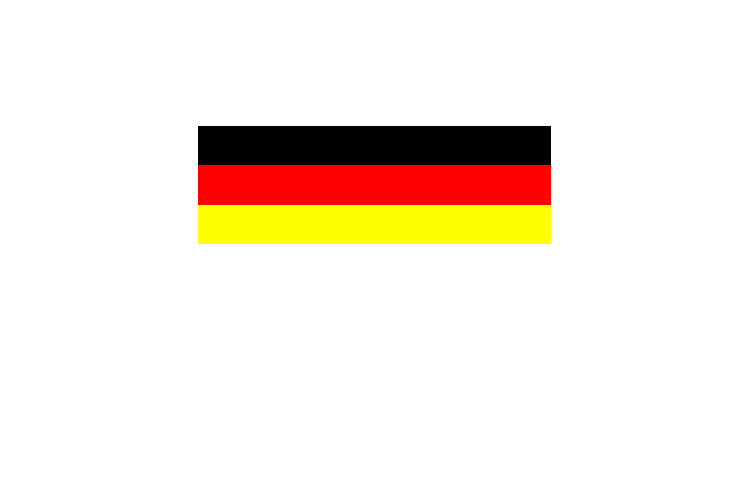

% Create an empty matrix 'pix' of size 300x900x3 with data type uint8
%%%YOUR CODE GOES HERE%%%

% Set the red stripe: Assign the maximum intensity value (255) to the red color channels 
% for all rows and columns from 301 to 600
%%%YOUR CODE GOES HERE%%%

% Set the yellow stripe: Assign the maximum intensity value (255) to the red and green channels (1st and 2nd dimension) 
% for all rows and columns from 601 to 900
%%%YOUR CODE GOES HERE%%%

% Display the generated image
%%%YOUR CODE GOES HERE%%%
